# Section 7: Final Project - Building your model

In the past couple weeks, you've learned a lot. On the programming side, you've learned how to import and interact with data, how images work, how to program machine learning, and more. On the AI side, you've learned about responsibility and ethics, different types of machine learning models, etc. Now it's time to synthesize all that knowledge for the final project.

For the final project, you will essentially be building and training a model that can take data and find the next big star. You have two paths to choose from: music or sports. You will need to find and import data, choose the best machine learning model, and determine parameters to extract from the data. Use this document as a reference, as everyone's projects will be specific to them and there is no right answer. I'll be using data from FIFA 23 as an example.

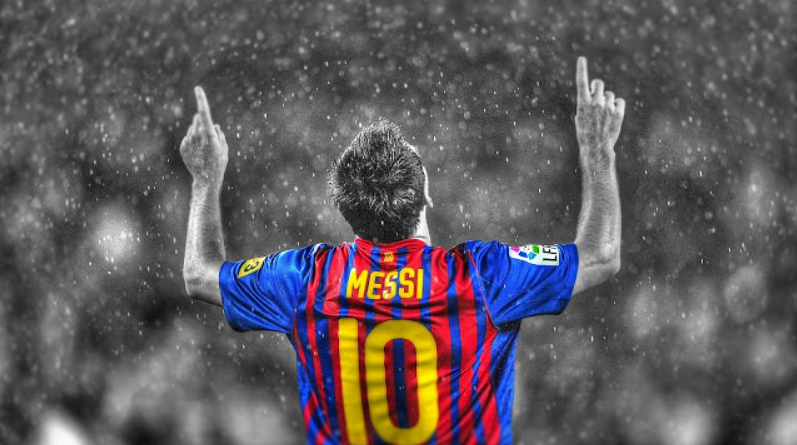

"[Lionel Messi](https://www.flickr.com/photos/121483302@N02/15748884358)" by [theglobalpanorama](https://www.flickr.com/photos/121483302@N02) is licensed under [CC BY-SA 2.0](https://creativecommons.org/licenses/by-sa/2.0/?ref=openverse).

## Step 1: Define success

Define what success means. What makes the next big athlete or music star popular and successful? For music, it could be based on metrics such as:

- number of hit songs

- Album sales

- Streaming counts

- Awards won

- Social media following

For sports, it may vary more depending on the sport you decide to analyze. Here are just a few examples for various scenarios:

- Individual athlete success: points scored, assists

- Awards and honors: MVP awards, All-Stars, Player of the Year awards

- Soccer: Goals scored, assists, dribbles completed

- Basketball: points per game, assists per game, Player Efficiency Rating (PER)

- American Football: passing yards, rushing yards, quarterback rating

- Baseball: Batting average, Home runs, runs batted in (RBIs)

For my example, the success metric is going to be the "Overall" column from the FIFA 23 data. These numbers are from the players' scores on various skills such as pace, defense, power, etc. We know that there is a direct relationship, but I will be using this to demonstrate how many predictor variables can be used in your model.

## Step 2: Import your sports or music data

In lesson 2, you learned how to locate and import data from various means. You've been provided a file about FIFA 2023 male players. Let's import it into Matlab.

fifa23 = readtable("/MATLAB Drive/MATLAB - Section 07 (Both - File Share)/Data/FIFA 23 male players.csv");
 

**Other methods of obtaining data**

I found the previous data online. You can use other methods that you've learned to obtain data, such as using API's or webscraping.

- for Spotify's API, see Lesson 3 development notebook

- for a sports API, see lesson 3 extension activity

- for webscraping, see Webscraping file

## Step 3: Identify Your Variables 

For most supervised machine learning models, it is necessary to split your data into predictor variables (also known as independent, features, or output variables) and response variables (also known as dependent, target, or output variables). This is because the purpose of the model is to use the predictor variables to understand the response variable.

The response variable is the players' Overall scores. The predictors would be the skill scores. In the FIFA 23 file some of the skills are very specific such as power long shot vs power strength or defending sliding tackle vs defending standing tackle. Instead we are going to use a few general skill scores such as shooting, passing, dribbling, and defending. 

Recap:

Response variable: **Players' Overall scores**

Predictor variables: **Shooting, passing, dribbling**, and **defending**. 

## Step 4: Split data into training and testing sets

Splitting the data can help prevent overfitting and underfitting. Overfitting data means that your model can only recognize patterns very specific to a single dataset, and can't recognize other data even if their valid. Underfitting is the opposite, where the model can't recognize other data because it's looking for patterns that are too broad. 

We're going to use the cvpartition function to partition the data for cross-validation.  This defines parts of the data to train the model, then to test it. For this example, its inputs are as follows:

- n- number of observations

- 'HoldOut'- this tells the function to divide the observations into a training set and a test (holdout) set

- p- the proportion of the dataset to hold out as the test set (commonly is 0.2)

Note that sometimes missing values such as NaNs in your data will need to be removed prior to partitioning the data into training and testing sets. This can be done using functions such as **rmmissing(). **

% Randomly partitions the data
cv = cvpartition(height(fifa23), 'HoldOut', 0.2);

% putting data from cvpartition into variables
trainData = fifa23(training(cv),:);
testData = fifa23(test(cv),:);
 

## Step 5: Finding your model

Your type of model depends on whether you define success as a continuous value (e.g., player goals each season) or a category (e.g., "successful" vs "not successful"). Regression models are used for continuous metrics, and classification models are for categorical.

Here are links that contain functions for each regression and classification model that may be useful. 

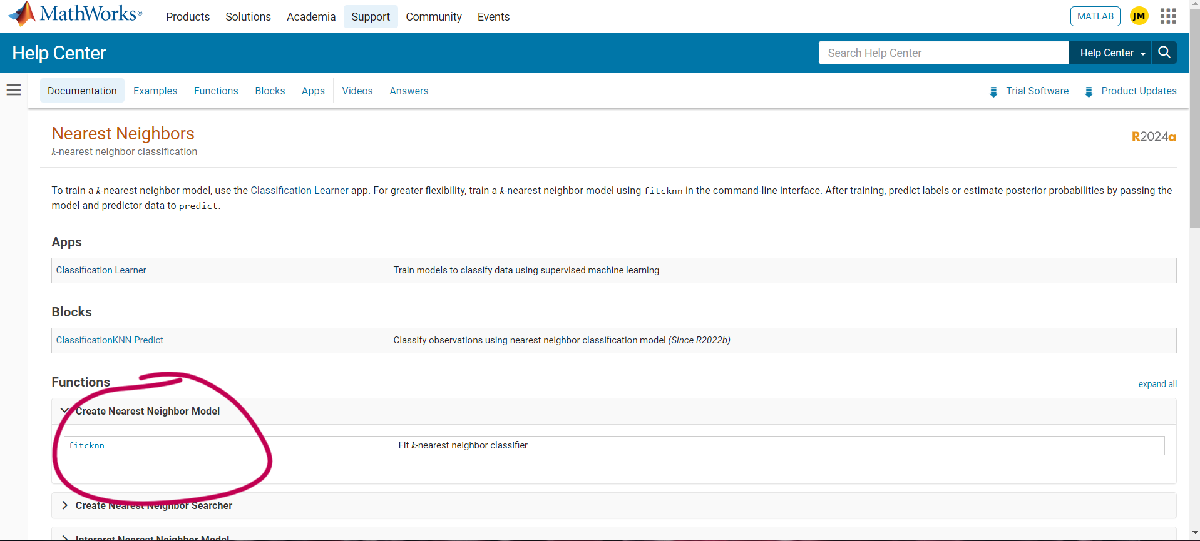

Clicking on a function will take you to a page that describes the possible inputs, definitions, and examples. If you don't see the model that you wish to use in the following list, go to the link under More to see more.

### Classification Models

Classification is a type of supervised machine learning in which an algorithm learns to classify new observations from examples of labeled data.

**Classification/Decision Trees**

- Binary decision trees for multiclass learning

- [https://www.mathworks.com/help/stats/classification-trees.html](https://www.mathworks.com/help/stats/classification-trees.html) 

**Discriminant Analysis**

- Regularized linear and quadratic discriminant analysis

- [https://www.mathworks.com/help/stats/classification-discriminant-analysis.html](https://www.mathworks.com/help/stats/classification-discriminant-analysis.html) 

**Naive Bayes**

- Naive Bayes model with Gaussian, multinomial, or kernel predictors

- [https://www.mathworks.com/help/stats/classification-naive-bayes.html](https://www.mathworks.com/help/stats/classification-naive-bayes.html) 

**Nearest Neighbors**

- *k*-nearest neighbor classification

- [https://www.mathworks.com/help/stats/classification-nearest-neighbors.html](https://www.mathworks.com/help/stats/classification-nearest-neighbors.html) 

**Support Vector Machine Classification**

- Support vector machines for binary or multiclass classification

- [https://www.mathworks.com/help/stats/support-vector-machine-classification.html](https://www.mathworks.com/help/stats/support-vector-machine-classification.html) 

**More**

- [https://www.mathworks.com/help/stats/classification.html](https://www.mathworks.com/help/stats/classification.html) 

### **Regression Models**

Regression models describe the relationship between a response (output) variable, and one or more predictor (input) variables.

**Linear Regression**

- Multiple, stepwise, multivariate regression models, and more

- [https://www.mathworks.com/help/stats/linear-regression.html](https://www.mathworks.com/help/stats/linear-regression.html) 

**Generalized Linear Models**

- Logistic regression, multinomial regression, Poisson regression, and more 

- [https://www.mathworks.com/help/stats/generalized-linear-models.html](https://www.mathworks.com/help/stats/generalized-linear-models.html) 

**Nonlinear Regression**

- Nonlinear fixed- and mixed-effects regression models

- [https://www.mathworks.com/help/stats/nonlinear-regression.html](https://www.mathworks.com/help/stats/nonlinear-regression.html) 

**Support Vector Machine Regression**

- Support vector machines for regression models

- [https://www.mathworks.com/help/stats/support-vector-machine-regression.html](https://www.mathworks.com/help/stats/support-vector-machine-regression.html) 

**More**

- [https://www.mathworks.com/help/stats/regression-and-anova.html](https://www.mathworks.com/help/stats/regression-and-anova.html) 

### Help Function

If you need a quick or additional help with a function, you can use the help function. If you want to keep it out of your code, run the command in the Command Window rather than the Livescript.

help fitcknn

  fitcknn fit KNN classification model
    KNN=fitcknn(TBL,Y) returns a KNN classification model for predictors X
    and response Y. TBL contains the predictor variables. Y can be any of
    the following: 
       1. An array of class labels. Y can be a categorical array, logical
          vector, numeric vector, string array or cell array of strings.
       2. The name of a variable in TBL. This variable is used as the
          response Y, and the remaining variables in TBL are used as
          predictors.
       3. A formula string such as 'y ~ x1 + x2 + x3' specifying that the
          variable y is to be used as the response, and the other variables
          in the formula are predictors. Any table variables not listed in
          the formula are not used.
 
    KNN=fitcknn(X,Y) is an alternative syntax that accepts X as an
    N-by-P matrix of predictors with one row per observation and one column
    per predictor. Y is the

## Step 6: Fitting a model to your data.

The next step is to fit the model to your data. Fitting a model to data is the process of finding a set of rules that best explain the relationship between the variables in your data, allowing you to make accurate predictions or understand the underlying patterns. For this example, I'm going to use a prebuilt function to fit a linear regression model.

A linear regression model is a mathematical method that finds the best-fitting straight line through a set of data points, representing the relationship between an independent variable (input) and a dependent variable (output). It is used to predict the value of the dependent variable based on the value of the independent variable.

Let's fit a linear regression model to see what relationship shooting, passing, dribbling, and defending have to a player's overall score.

mdl = fitlm(trainData,'overall ~ shooting + passing + dribbling + defending')

mdl = Linear regression model:
    overall ~ 1 + shooting + passing + dribbling + defending

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      26.196     0.096056    272.72             0
    shooting        0.21861    0.0016581    131.85             0
    passing        0.014379    0.0026102     5.509    3.6167e-08
    dribbling       0.24373    0.0026017    93.678             0
    defending       0.24063    0.0010655    225.84             0


Number of observations: 114930, Error degrees of freedom: 114925
Root Mean Squared Error: 4.2
R-squared: 0.633,  Adjusted R-Squared: 0.633
F-statistic vs. constant model: 4.97e+04, p-value = 0

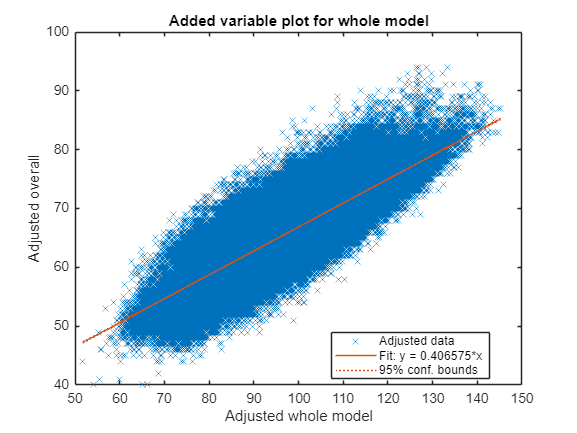

plot(mdl)

## The Next Steps

Each type of machine learning model provides different outputs and metrics based on its unique characteristics. It is essential to understand these outputs to evaluate the model's performance and interpret the relationships between predictors and the response variable effectively. In the next couple of lessons you will evaluate the model, refine, then finalize your model.